# The MSIR Model

#### **The Model**

The MSIR model was developed to describe the dynamics of an infectious disease, which does not affect babies in their early stage of life, such as measles. This so-called **natant passive immunity** or **maternity immunity** is due to maternal antibodies transferred to the fetus through the placenta. However, immunity is lost as soon as the baby runs out of maternal antibodies. From then on, the natant becomes susceptible to contract the disease.

In the MSIR model the three compartments of the simpler SIR model are preceeded by one additional phase: the immune from birth (M), the susceptible (S), the infected (I) and the recovered (R). The flow of individuals from one compartment to another is described in terms of four differential equations, reported below.

Unlike the SIR model, the MSIR model has to take into account **vital dynamics**, because a **constant birth rate** underpins the nature of the M compartment. As a result, the total number of the population slightly increases with time: $N_0=M_0+S_0+I_0+R_0<M(t)+S(t)+I(t)+R(t)$. Even though this creates a systemic error, death rate can be neglected, as individuals die at a relatively smaller rate than they are born.

The image below shows what the block diagram for the MSIR model looks like.

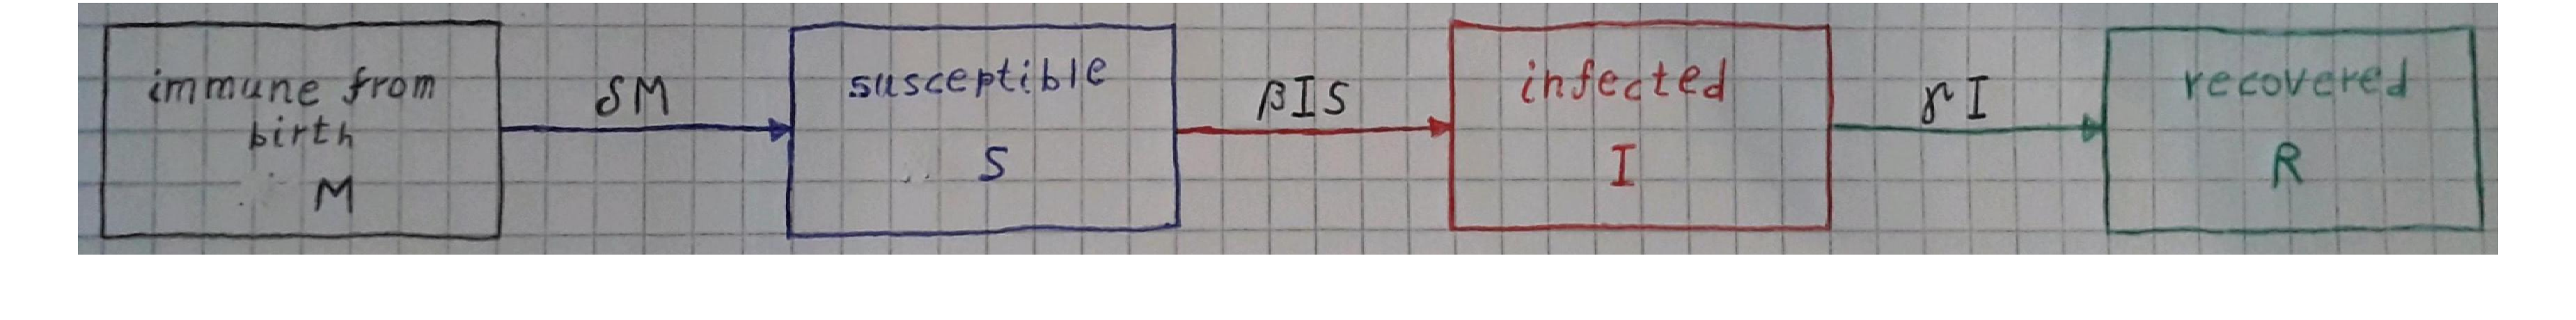

imshow('MSIR_block_diagram.jpg')

The differential equations of the MSIR model are:


$$\frac{dM}{dt}=\Lambda - \delta M,$$



$$\frac{dS}{dt}=-\beta I S,\\
\frac{dI}{dt}=\beta IS-\gamma I,\\
\frac{dR}{dt}=\gamma I.
$$


The parameters are:

- $\beta$ is referred to as the infection rate and is defined as the product between the infection probability $p$ and the contact rate $c$, divided by the total population. In fact, its value depends on the transmissability of the disease, which is accounted for with $p$, and the frequency that members of a population gather for social reasons, which is expressed as $c$.

- $\gamma$ corresponds to the recovery rate. Its value relies on the virulence or pathogenicity of the organism responsible for the disease as well as the average physical and mental conditions of the population, which can also affect how drammatically an individual will experience related symptoms.

- $\Lambda$ expresses the daily number of births, which is assumed to be constant. Odbviously, this parameter relies to a large extent on the examined country and the social behaviour of its population, thus different communities will be featured by different constant values of $\Lambda$.

- $\delta$ accounts for the rate at which newborns lose the privilege of maternal immunity. It varies across different types of infectious diseases and its optimal value can be estimated by comparison with and fitting of real data.

## Solution with Euler method

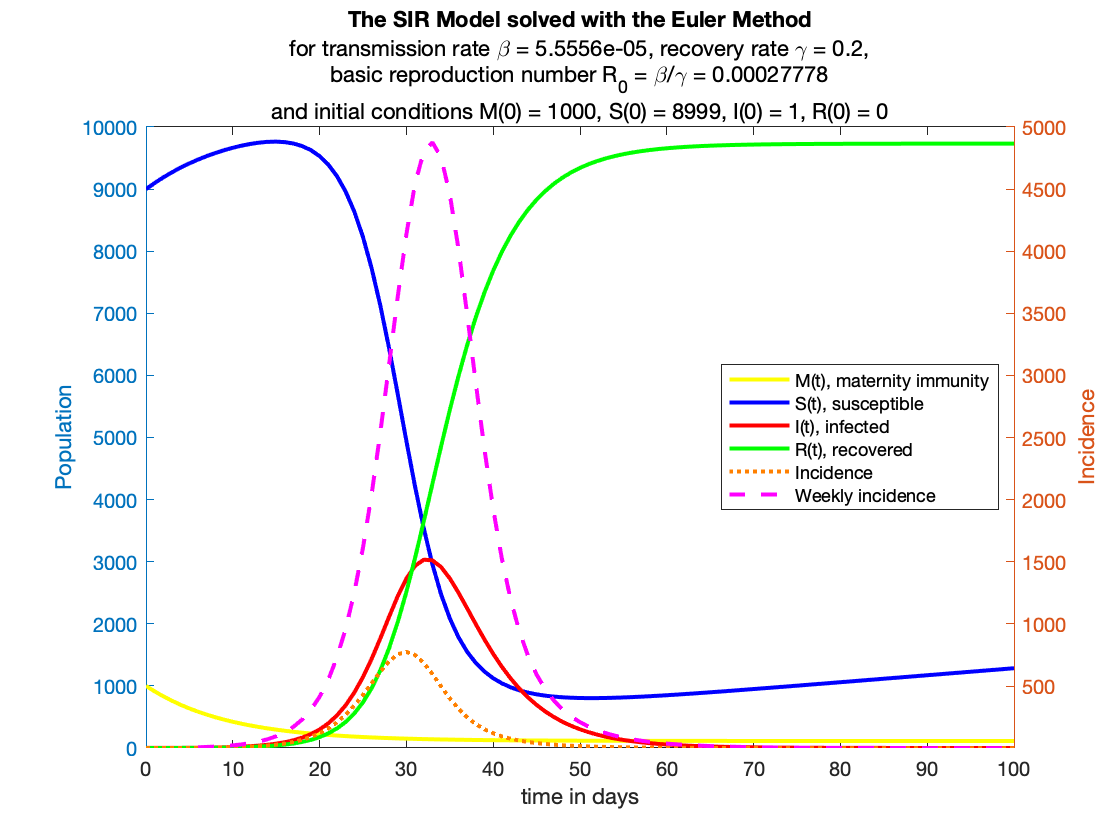

figure;

%%% The initial values

tmax = 100;

M = zeros(1, tmax + 1);
S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);
R = zeros(1, tmax + 1);

M(1) = 1000;
S(1) = 8999;
I(1) = 1;
R(1) = 0;
N=S(1)+I(1)+R(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.1;  % infection probability 
c=5;    % contact rate

beta = p*c/N;
gamma = 0.2;

delta = 0.1;    % rate of loss of passive immunity
Lambda = 11.3;  % daily number of births

mu = 3.5E-4;  % death rate

R_0=beta/gamma;
% Imax = N/R_0*(R_0-1-log(R_0))

%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
    
    M(t+1) = lambda + M(t) - sigma*M(t);
    S(t+1) = S(t) - beta*I(t)*S(t) + sigma*M(t);   
    I(t+1) = I(t) + (beta*I(t)*S(t)) - gamma*I(t);    
    R(t+1) = R(t) + gamma*I(t);
    
    Incidence(t+1) = beta*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end


%%%% The plot

yyaxis left
plot(T, M, 'y','LineWidth',2,'Linestyle',"-"); hold on;
plot(T, S, 'b','LineWidth',2,'LineStyle',"-");
plot(T, I, 'r','LineWidth',2,'LineStyle',"-");
plot(T, R, 'g','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right 
plot(T, Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(T(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylim([1 5000]);
ylabel('Incidence');

title('The SIR Model solved with the Euler Method')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions M(0) = ',num2str(M(1)),', S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1)),', R(0) = ',num2str(R(1))]})
legend('M(t), maternity immunity', 'S(t), susceptible', 'I(t), infected', 'R(t), recovered','Incidence', 'Weekly incidence', 'Location', 'east')

xlabel('time in days');
xlim([0 100]);

hold off;